# 2. Interpreting Network - Convolution, ReLU, Max Pooling Layers

## Activations(정보 사이에 전해지는 것들, 결과값. Output X)

image = imread("face.jpg")

image = 384×384×3 uint8 배열
image(:,:,1) =

   231   231   231   231   231   231   231   231   232   232   232   231   231   230   230   230   231   231   231   231   231   231   231   231   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   233   233   233   233   233   233   233   233   231   231   231   231   231   231   231   231   232   232   232   232   232   232   232   232   231   231   231   231   231   231   231   231   229   229   230   231   233   234   235   235   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   233   233   233   233   233   233   233   

sz = size(image)

sz =    384   384     3


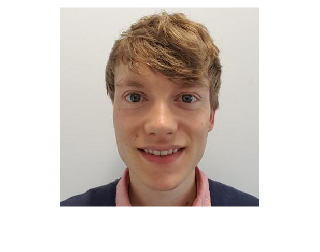

imshow(image)

net = squeezenet; % Load SqueezeNet %SqueezeNet을 사용하는 이유를 알아야함.
layers = net.Layers % Save and view the layers of SqueezeNet

layers =   다음 계층을 포함한 68×1 Layer 배열:

     1   'data'                              영상 입력              227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'                             2차원 컨벌루션          64개 3×3×3 컨벌루션(스트라이드: [2  2], 채우기: [0  0  0  0])
     3   'relu_conv1'                        ReLU                  ReLU
     4   'pool1'                             2차원 최댓값 풀링       3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     5   'fire2-squeeze1x1'                  2차원 컨벌루션          16개 1×1×64 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     6   'fire2-relu_squeeze1x1'             ReLU                  ReLU
     7   'fire2-expand1x1'                   2차원 컨벌루션          64개 1×1×16 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     8   'fire2-relu_expand1x1'              ReLU                  ReLU
     9   'fire2-expand3x3'                   2차원 컨벌루션          64개 3×3×16 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    10   'fir

View the network architecture

% 앱즈, 딮 네트워크 디자이너, 스퀴즈 넷, 심층 신경망 디자이너
analyzeNetwork(net)

% layers(end) % OutputSize 1000개
layers(2)

ans =   Convolution2DLayer - 속성 있음:

              Name: 'conv1'

   하이퍼파라미터
        FilterSize: [3 3]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [0 0 0 0]
      PaddingValue: 0

   학습 가능한 파라미터
           Weights: [3×3×3×64 single]
              Bias: [1×1×64 single]

  모든 속성 표시


% 하이퍼파라미터 : 학습이 진행되면서 숫자가 바뀐것 X 정해져있는것. 내가 정하는 것.
% NumChannels : 인풋 채널 3개, NumFilters : 아웃풋 채널 64개

### Show Activations of First Convolutional Layer(컨볼류션의 필터의 갯수는 analyzeNetwork 3번째) > 첫번째 컨볼루젼 레이어의 액티베이션 보이기

Activation: Information passed between the network layers.(하나의 레이어를 지나칠때 나오는 결과 물)

You can extract the activations from a layer by using `activations` function.

layers(2) % View the hyperparameters and learnable parameters of the first convolution layer

ans =   Convolution2DLayer - 속성 있음:

              Name: 'conv1'

   하이퍼파라미터
        FilterSize: [3 3]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [0 0 0 0]
      PaddingValue: 0

   학습 가능한 파라미터
           Weights: [3×3×3×64 single]
              Bias: [1×1×64 single]

  모든 속성 표시


actvn1 = activations(net,image,"conv1") % Extract the activations from the first convolution layer

actvn1 = 191×191×64 single 배열
actvn1(:,:,1) =

    0.1633    0.1633    0.1633   -0.0847    1.0351    0.8815   -0.4155   -0.2686    0.1792    0.1792    0.1792   -0.0689    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811   -0.0670    0.1829    0.1829    0.1829    0.6791    0.1792    0.1792    0.1792   -0.0689    0.1811    0.1811    0.1811   -0.8004   -3.3900   -3.3900   -3.3900   -4.6336   -7.1019   -2.1452    5.8226    5.8607    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811    0.1811   -0.0670    0.1829    0.1829    0.1829    1.1701    1.7642    1.4539    1.4539    1.2058    1.4558    1.4558    1.4558    4.2667    1.7913   -5.2019   -2.9748   -5.6661   -7.3560   18.6434   10.3184   

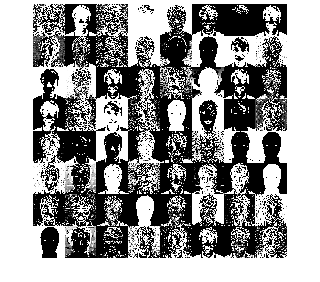

% 필터는 좌에서 우 방향으로
% Display the activation extracted from "conv1"
montage(actvn1)

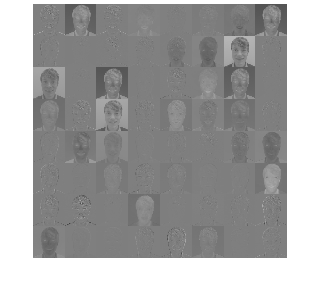

image1 = mat2gray(actvn1);
montage(image1)

### Investigate the activations in specific channels

(특정 채널의 활성화 조사)

Each tile in the grid of activations is the output of a channel in the `conv1` layer. White pixels represent strong positive activations and black pixels represent strong negative activations. A channel that is mostly gray does not activate as strongly on the input image. The position of a pixel in the activation of a channel corresponds to the same position in the original image. A white pixel at some location in a channel indicates that the channel is strongly activated at that position.

For channel 41,

"3번째 열"은 3번째 필터의 활성화를 나타내며, 이 활성화는 해당 필터가 감지한 이미지의 특정 특징을 나타내는 채널의 순서를 의미합니다.

활성화 그리드의 각 타일은 conv1 레이어에 있는 채널의 출력입니다. 흰색 픽셀은 강한 긍정적인 활성화를 나타내고 검은색 픽셀은 강한 부정적인 활성화를 나타냅니다. 대부분 회색인 채널은 입력 이미지에서 강하게 활성화되지 않습니다. 채널 활성화 시 픽셀 위치는 원본 이미지의 위치와 동일합니다. 채널의 일부 위치에 있는 흰색 픽셀은 해당 위치에서 채널이 강하게 활성화되었음을 나타냅니다.

채널 41의 경우,

actvn1_ch41 = actvn1(:,:,41)

actvn1_ch41 = 191×191 single 행렬
    2.0125    2.0125    2.0125    0.0792    3.4322    2.5663    1.9935   -0.6866    2.0452    2.0452    2.0452    0.1120    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634    0.1302    2.0816    2.0816    2.0816    5.9481    2.0452    2.0452    2.0452    0.1120    2.0634    2.0634    2.0634    1.9222    1.2427    1.2427    1.2427    2.3062   -3.2376    0.9713    3.7728    7.7550    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634
    2.8150    2.8150    2.8150    0.8817    2.6920    2.0125    1.8713    0.5853    2.0452    2.0452    2.0452    2.1864    2.8659    2.8659    2.8659    0.7915    2.0634    2.0634    2.0634    2.2047    2.8842    2.8842    2.8842    4.6762    2.0452    2.0452    2.0452    0.1120    2.0634    2.0634    2.0634   -0.0110    1.2609    1.2609    1.2609   -0.1406    0.7064    2.9697    5.1737    1.3460    2.0634    2.0634    2.0634    2.0634    2.0634    2.0634    2.0

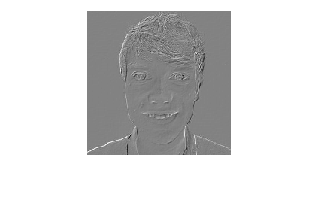

actvn1_ch41 = mat2gray(actvn1_ch41);
imshow(actvn1_ch41) %원본 이미지랑 비교해야함 그러기 위해서는 resize가 필요

actvn1_ch41 = imresize(actvn1_ch41,sz(1:2)) % resize the activation in channel 41 in order to compare it with the original image

actvn1_ch41 =     0.5105    0.5105    0.5105    0.5106    0.5108    0.5096    0.5068    0.5075    0.5122    0.5141    0.5127    0.5118    0.5114    0.5095    0.5056    0.5052    0.5091    0.5112    0.5110    0.5108    0.5111    0.5100    0.5071    0.5065    0.5093    0.5109    0.5108    0.5106    0.5106    0.5107    0.5110    0.5111    0.5109    0.5108    0.5108    0.5109    0.5111    0.5103    0.5074    0.5065    0.5091    0.5109    0.5109    0.5106    0.5100    0.5115    0.5171    0.5191    0.5142    0.5104
    0.5110    0.5110    0.5110    0.5111    0.5113    0.5101    0.5073    0.5078    0.5120    0.5136    0.5123    0.5115    0.5113    0.5097    0.5062    0.5059    0.5093    0.5111    0.5109    0.5108    0.5110    0.5102    0.5080    0.5077    0.5100    0.5114    0.5113    0.5112    0.5112    0.5110    0.5106    0.5104    0.5106    0.5108    0.5108    0.5108    0.5111    0.5104    0.5082    0.5077    0.5098    0.5114    0.5113    0.5111    0.5106    0.5119    0.5167    0.5184    0

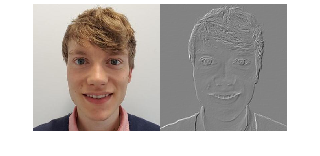

 % Display the original image and the activation in channel 41
montage({image,actvn1_ch41}) %셀 형태로 바꿔줌

For channel 22,

actvn1_ch22 = actvn1(:,:,22)

actvn1_ch22 = 191×191 single 행렬
   -2.5889   -2.5889   -2.5889   -2.6159   -2.6112   -2.6329   -2.5829   -1.8234    0.0131    0.0131    0.0131   -0.0139   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0672   -0.0935   -0.0935   -0.0935   -0.0395    0.0131    0.0131    0.0131   -0.0139   -0.0402   -0.0402   -0.0402   -0.0307   -0.0312   -0.0312   -0.0312   -0.0392    0.0108   -0.0064   -0.0202   -0.0857   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402
   -2.5446   -2.5446   -2.5446   -2.5716   -2.5883   -2.5889   -2.5793   -1.8503    0.0131    0.0131    0.0131    0.0035    0.0041    0.0041    0.0041   -0.0134   -0.0402   -0.0402   -0.0402   -0.0498   -0.0492   -0.0492   -0.0492   -0.0127    0.0131    0.0131    0.0131   -0.0139   -0.0402   -0.0402   -0.0402   -0.0577   -0.0845   -0.0845   -0.0845   -0.1155   -0.0878   -0.0825   -0.0072   -0.0101   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0402   -0.0

actvn1_ch22 = mat2gray(actvn1_ch22)

actvn1_ch22 =     0.1515    0.1515    0.1515    0.1514    0.1514    0.1513    0.1516    0.1561    0.1671    0.1671    0.1671    0.1670    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1667    0.1665    0.1665    0.1665    0.1668    0.1671    0.1671    0.1671    0.1670    0.1668    0.1668    0.1668    0.1669    0.1669    0.1669    0.1669    0.1668    0.1671    0.1670    0.1669    0.1665    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668
    0.1518    0.1518    0.1518    0.1516    0.1515    0.1515    0.1516    0.1560    0.1671    0.1671    0.1671    0.1671    0.1671    0.1671    0.1671    0.1670    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1670    0.1671    0.1671    0.1671    0.1670    0.1668    0.1668    0.1668    0.1667    0.1665    0.1665    0.1665    0.1664    0.1665    0.1666    0.1670    0.1670    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0

actvn1_ch22 = imresize(actvn1_ch22,sz(1:2))% resize the activation in channel 22 in order to compare it with the original image

actvn1_ch22 =     0.1515    0.1515    0.1515    0.1515    0.1515    0.1515    0.1514    0.1514    0.1514    0.1514    0.1513    0.1512    0.1512    0.1522    0.1542    0.1582    0.1645    0.1678    0.1675    0.1671    0.1671    0.1671    0.1670    0.1669    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1667    0.1666    0.1665    0.1665    0.1665    0.1665    0.1664    0.1665    0.1667    0.1668    0.1670    0.1671
    0.1516    0.1516    0.1516    0.1516    0.1516    0.1516    0.1515    0.1514    0.1514    0.1514    0.1513    0.1513    0.1512    0.1522    0.1542    0.1582    0.1645    0.1678    0.1675    0.1671    0.1671    0.1671    0.1670    0.1670    0.1669    0.1668    0.1669    0.1669    0.1669    0.1669    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1668    0.1667    0.1666    0.1666    0.1665    0.1665    0.1665    0.1665    0.1666    0.1667    0.1669    0

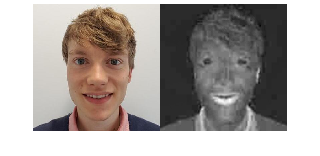

montage({image,actvn1_ch22}) % Display the original image and the activation in channel 22

## Deeper Layer Activations

(심층 레이어 활성화)

Most convolutional neural networks learn to detect features like color and edges in their first convolutional layer. In deeper convolutional layers, the network learns to detect more complicated features. Later layers build up their features by combining features of earlier layers. Investigate the `fire6-squeeze1x1` layer in the same way as the `conv1` layer. Calculate, reshape, and show the activations in a grid.

대부분의 컨볼루셔널 신경망은 첫 번째 컨볼루션 레이어에서 색상 및 가장자리와 같은 특징을 감지하는 방법을 학습합니다. 더 깊은 컨벌루션 레이어에서 네트워크는 더 복잡한 특징을 감지하는 방법을 학습합니다. 이후 레이어는 이전 레이어의 기능을 결합하여 기능을 구축합니다. conv1 레이어와 동일한 방식으로 fire6-squeeze1x1 레이어를 조사합니다. 그리드에서 활성화를 계산하고 모양을 변경하고 표시합니다.

actvn6 = activations(net,image,"fire6-squeeze1x1")% Extract the activations from "fire6-squeeze1x1" layer

actvn6 = 23×23×48 single 배열
actvn6(:,:,1) =

  129.4550   85.7527   59.4076   71.5333   82.3778   96.3230   93.6582    3.7620  -97.7362 -269.3254 -100.0954   23.0344 -133.3718 -149.0391    7.1645  138.0941   18.7708   70.3652  100.2226   74.9454   73.0919   75.9598   74.6420
   22.7667   20.2157    1.2557    7.6808    8.6970    2.3361  -27.4168 -152.8305 -108.7198 -114.7665  -43.7269   21.0280   17.0411  106.3885  218.3085   97.8596  -68.7969  -89.3010   36.5738   26.0875    6.6113   12.4167    5.2402
   19.9638   11.6099   -4.6195   -1.8408    2.8660  -35.1879  -80.8414  -69.5859   49.6175  115.2638   89.2821    3.1837   -4.8169   70.4282  108.6202   32.0218   55.0852   49.8635   18.9246   62.6166   12.7586    5.8803   -5.6000
   15.2440    6.4061   -7.4767   -2.8056   -9.6717  -78.4361  -51.8258  -28.4228  139.1640   57.6270   60.3458   60.8537   63.1080   97.1340   63.3905   -0.4450   62.1914  114.8438  -33.9879    1.5966   23.3735    7.4324  -11.3728
    6.7515    9.1377    1.7573 

actvn6 = mat2gray(actvn6)

actvn6 = actvn6(:,:,1) =

    0.4632    0.4439    0.4323    0.4377    0.4424    0.4486    0.4474    0.4078    0.3631    0.2874    0.3620    0.4163    0.3474    0.3404    0.4093    0.4670    0.4144    0.4372    0.4503    0.4392    0.4384    0.4396    0.4390
    0.4162    0.4150    0.4067    0.4095    0.4100    0.4072    0.3941    0.3388    0.3582    0.3556    0.3869    0.4154    0.4136    0.4530    0.5024    0.4493    0.3758    0.3668    0.4223    0.4176    0.4091    0.4116    0.4084
    0.4149    0.4113    0.4041    0.4053    0.4074    0.3906    0.3705    0.3755    0.4280    0.4569    0.4455    0.4075    0.4040    0.4372    0.4540    0.4203    0.4304    0.4281    0.4145    0.4337    0.4118    0.4087    0.4037
    0.4129    0.4090    0.4028    0.4049    0.4019    0.3716    0.3833    0.3936    0.4675    0.4315    0.4327    0.4330    0.4340    0.4490    0.4341    0.4059    0.4336    0.4568    0.3912    0.4068    0.4164    0.4094    0.4011
    0.4091    0.4102    0.4069    0.4073    0.4070

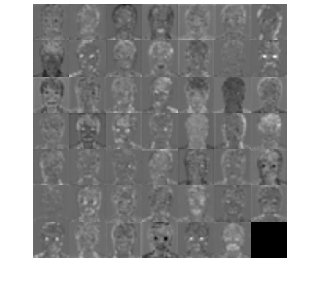

montage(actvn6)% Display the activation extracted from "fire6-squeeze1x1"

For channel 47,

actvn6_ch47 = actvn6(:,:,47)

actvn6_ch47 =     0.4267    0.4298    0.4258    0.4301    0.4344    0.4403    0.4470    0.3855    0.3669    0.3411    0.3485    0.3545    0.3734    0.4014    0.3966    0.4375    0.4052    0.3931    0.4366    0.4342    0.4314    0.4295    0.4310
    0.4086    0.4100    0.4050    0.4077    0.4089    0.4073    0.3594    0.3169    0.3405    0.3355    0.3677    0.3941    0.3626    0.3812    0.4170    0.4640    0.3966    0.3694    0.3964    0.4084    0.4082    0.4068    0.4066
    0.4076    0.4076    0.4043    0.4061    0.4020    0.4115    0.3896    0.3350    0.4062    0.3783    0.3848    0.4303    0.3865    0.3549    0.3802    0.3715    0.3687    0.3687    0.3946    0.4075    0.4066    0.4079    0.4045
    0.4064    0.4068    0.4053    0.4053    0.3936    0.3655    0.3554    0.3532    0.3854    0.3872    0.4073    0.4234    0.3600    0.3402    0.3866    0.3712    0.3708    0.3621    0.3950    0.3758    0.4056    0.4077    0.4083
    0.4043    0.4071    0.4079    0.4046    0.3887    0.3447  

actvn6_ch47 = mat2gray(actvn6_ch47)

actvn6_ch47 =     0.2427    0.2486    0.2408    0.2491    0.2575    0.2688    0.2817    0.1628    0.1269    0.0770    0.0913    0.1030    0.1395    0.1937    0.1843    0.2635    0.2010    0.1775    0.2616    0.2571    0.2517    0.2481    0.2510
    0.2075    0.2103    0.2006    0.2059    0.2081    0.2051    0.1125    0.0304    0.0760    0.0663    0.1286    0.1795    0.1186    0.1546    0.2239    0.3147    0.1843    0.1317    0.1841    0.2071    0.2067    0.2041    0.2037
    0.2057    0.2056    0.1993    0.2028    0.1948    0.2132    0.1709    0.0652    0.2029    0.1490    0.1616    0.2496    0.1648    0.1038    0.1526    0.1358    0.1304    0.1305    0.1805    0.2054    0.2037    0.2063    0.1997
    0.2033    0.2041    0.2013    0.2011    0.1785    0.1242    0.1047    0.1005    0.1628    0.1661    0.2050    0.2362    0.1137    0.0753    0.1650    0.1352    0.1346    0.1177    0.1812    0.1442    0.2017    0.2058    0.2071
    0.1993    0.2046    0.2063    0.1999    0.1691    0.0840  

sz(1:2)

ans =    384   384


actvn6_ch47 = imresize(actvn6_ch47,sz(1:2))% resize the activation in channel 47 in order to compare it with the original image

actvn6_ch47 =     0.2463    0.2463    0.2463    0.2464    0.2465    0.2466    0.2467    0.2469    0.2471    0.2473    0.2476    0.2480    0.2485    0.2490    0.2495    0.2500    0.2506    0.2511    0.2516    0.2520    0.2525    0.2528    0.2531    0.2533    0.2533    0.2533    0.2531    0.2528    0.2524    0.2519    0.2513    0.2507    0.2500    0.2493    0.2487    0.2480    0.2474    0.2469    0.2464    0.2461    0.2459    0.2458    0.2458    0.2460    0.2463    0.2466    0.2471    0.2476    0.2481    0.2487
    0.2461    0.2462    0.2462    0.2463    0.2464    0.2465    0.2466    0.2468    0.2469    0.2472    0.2475    0.2479    0.2484    0.2488    0.2494    0.2499    0.2504    0.2510    0.2515    0.2519    0.2523    0.2527    0.2529    0.2531    0.2532    0.2532    0.2530    0.2527    0.2523    0.2518    0.2512    0.2505    0.2499    0.2492    0.2485    0.2479    0.2473    0.2467    0.2463    0.2459    0.2457    0.2456    0.2457    0.2459    0.2461    0.2465    0.2469    0.2474    0

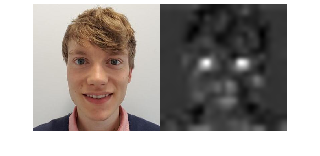


montage({image,actvn6_ch47}) % Display the original image and the activation in channel 47

## Following Activations in the Network Architecture

### Rectified Linear Unit (ReLU) Layer

(네트워크 아키텍처에서 활성화 가져오기) -> ReLU(수정 선형 단위) 계층

ReLu layer apply a threshold to an input such that every value less than zero is set to zero. You will see that any negative activations from a convolution layer will be set to zero after passing through the ReLU layer.

ReLu 레이어는 0보다 작은 모든 값이 0으로 설정되도록 입력에 임계값을 적용합니다. 컨볼루션 레이어의 모든 음수 활성화는 ReLU 레이어를 통과한 후 0으로 설정되는 것을 볼 수 있습니다.

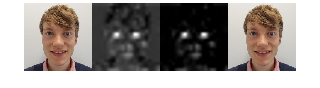

 % Extract the activations from "fire6-relu_squeeze1x1" layer
actvn6_relu = activations(net, image, "fire6-relu_squeeze1x1");
actvn6_relu_ch47 = actvn6_relu(:,:,47);
actvn6_relu_ch47 = mat2gray(actvn6_relu_ch47);
actvn6_relu_ch47 = imresize(actvn6_relu_ch47, sz(1:2));

montage({image, actvn6_ch47, actvn6_relu_ch47, image}, "Size",[1,4])

### Max Pooling Layer

Max pooling layers perform downsampling, which causes large activations to be more pronounced after passing through the pooling layer.

최대 풀링 계층은 다운샘플링(입력된 이미지나 특징 맵의 크기를 줄이기)을 수행하므로 풀링 계층을 통과한 후 큰 활성화가 더 뚜렷해집니다.

간단히 말하면, 최대 풀링 계층은 중요한 정보를 유지하면서 공간 해상도를 줄여 계산 효율성을 높이는 역할을 합니다. 이렇게 하면 네트워크가 더 깊어지고 복잡해질 때도 효과적으로 작동할 수 있습니다.

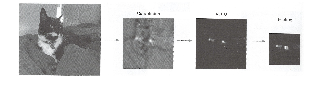

cnnLayerBehavior = imread("cnnLayerBehavior.jpg");
imshow(cnnLayerBehavior)